# HW 3 Problem 4.59

clear; clc; close;

## Check for solutions

% s_1 = s_2 = 0
A = [2,0,-1,-1;...
    0,2,-1,1;...
    -1,-1,0,0;...
    -1,1,0,0]

A =      2     0    -1    -1
     0     2    -1     1
    -1    -1     0     0
    -1     1     0     0


inv(A)

ans =          0         0   -0.5000   -0.5000
         0         0   -0.5000    0.5000
   -0.5000   -0.5000   -1.0000         0
   -0.5000    0.5000         0   -1.0000


c = [2;2;-4;-2]

c =      2
     2
    -4
    -2


inv(A)*c

ans =      3
     1
     2
     2



% test the other cases

% u_1 = s_2 = 0
filter = [1,2,4]

filter =      1     2     4


A(filter,filter);
c(filter);
inv(A(filter,filter)) * c(filter)

ans =      2
     0
     2




% s_1 = u_2 = 0
filter = [1,2,3]

filter =      1     2     3


A(filter,filter);
c(filter);
inv(A(filter,filter)) * c(filter)

ans =      2
     2
     2




% u_1 = u_2 = 0
filter = [1,2]

filter =      1     2


A(filter,filter);
c(filter);
inv(A(filter,filter)) * c(filter)

ans =      1
     1


## Delcare Plotting variables

clear; clc; close;
domain = [-5,5];
range = [-5,5];
n_pointsPlot = 1000;

## plot

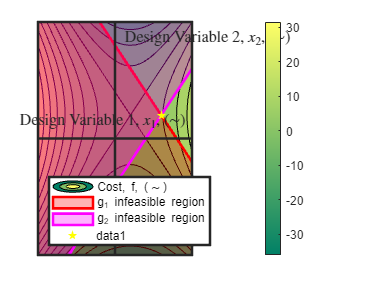

x_1 = linspace(domain(1), domain(2), floor(sqrt(n_pointsPlot)));
x_2 = linspace(range(1), range(2), floor(sqrt(n_pointsPlot)));

[x_1_grid, x_2_grid] = meshgrid(x_1,x_2);

f = (x_1_grid-1).^2 - (x_2_grid-1).^2;

contourf(x_1_grid, x_2_grid, f, 15, "LineWidth",.001, "DisplayName","Cost, f, (\sim)"); colormap("summer"); colorbar;
zlabel("Cost, f, (\sim)",Interpreter="latex");
xlabel("Design Variable 1, $x_1$, $(\sim)$", "Interpreter","latex", "FontSize",12);
ylabel("Design Variable 2, $x_2$, $(\sim)$", "Interpreter","latex", "FontSize",12);
xlim(domain); ylim(range);

% constraints
hold on
%g_1
boundrayEdges_Xcoords = [x_1, fliplr(x_1)];
boundrayEdges_Ycoords = [4-x_1, range(1) * ones(1,length(x_2))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0], "LineWidth",2, "DisplayName","g_1 infeasible region")
%g_2
boundrayEdges_Xcoords = [x_1, fliplr(x_1)];
boundrayEdges_Ycoords = [x_1-2, range(2) * ones(1,length(x_2))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,1], "FaceAlpha",.3, "EdgeColor",[1,0,1], "LineWidth",2, "DisplayName","g_2 infeasible region")

% plot the optimum
plot(3,1,"Marker","pentagram","MarkerSize",6,"MarkerEdgeColor",[1,1,0],"MarkerFaceColor",[1,1,0],"LineStyle","none")

% plot better 
box(gca,'on'); % hide the fact that my regions are bordered on the edge of the graph
set(gca,'BoxStyle','full','Layer','top','XAxisLocation','origin',...
    'YAxisLocation','origin');
set(gca,"LineWidth",2)
legend("Location","southwest")